clear,close all,clc,
tic,

t0=0;
tf=100;

A=[3 2 0 0 0;
    0 3 2 0 0;
    0 0 3 2 0;
    0 0 0 3 2;
    1 6 8 24 16];

u0=5*cos(0)+6*exp(-0.5*0)*sin(0+pi/3);

B=[1;2;-3;2;u0];

Z=inv(A)*B;

x1=Z(1);
x2=Z(2);
x3=Z(3);
x4=Z(4);

xinitial=[x1;x2;x3;x4];

[tout,stateout]=ode45(@stateequation04,[t0,tf],xinitial);

x1out=stateout(:,1);
x2out=stateout(:,2);
x3out=stateout(:,3);
x4out=stateout(:,4);

yout=2*x2out+3*x1out;

s=j*1;
H=(2*s+3)/(s^4+6*s^3+18*s^2+24*s+16);
K=norm(H),

K = 0.2000

phi=angle(H),

phi = -1.0383

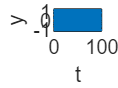


figure,
plot(tout,K*6*sin(tout+pi/3+phi),'LineWidth',2),
% plot(tout,yout,'LineWidth',2),
ylabel('y'),
xlabel('t'),
grid on,


toc,

历时 0.336313 秒。


function statedot=stateequation04(t,state)

x1=state(1);
x2=state(2);
x3=state(3);
x4=state(4);

x1dot=x2;
x2dot=x3;
x3dot=x4;
u=5*cos(t)+6*exp(-0.5*t)*sin(t+pi/3);
x4dot=u-6*x4-18*x3-24*x2-16*x1;

statedot=[x1dot;x2dot;x3dot;x4dot];
end